%Loading Data
droughtdata = load("droughtdata.txt");
years = 2000:1:2020;
years=years';
wind00_05 = load("wind00_05.txt");
wind02_05 =load("wind_02_05.txt");
wind06_10 = load("wind06_10.txt");
wind08_09 = load("wind08_09.txt");
wind10_12 = load("wind10_12.txt");
wind13_14 = load("wind_13_14.txt");
wind15_17 = load("wind15_17.txt");
wind17_19 = load("wind17_19.txt");
wind20 = load("wind_20.txt");
[r, c]=find(wind00_05(:,5)==0);
wind00_05(r,:)=[];

wind = [wind00_05; wind02_05; wind06_10; wind08_09; wind10_12; wind13_14; wind15_17; wind17_19; wind20 ];

count_by_year=[7622, 9317, 8171, 8287, 7898, 7237, 7855, 6043, 6255, 7010, 6394, 7732, 7041, 8889, 7233, 8283, 6959, 9270, 7948, 7915, 8648]';
acres = [295026, 377340, 538216, 965770, 311024, 279214, 863345, 1520362, 1593690, 451969, 134462, 228599, 829224, 601635, 625540, 880899, 669534, 1548429, 1975086, 1059051, 4304379]';

%Data Processing
dnonetot = droughtdata(:,5);
d0total = droughtdata(:, 6);
d1total = droughtdata(:, 7);
d2total = droughtdata(:, 8);
d3total = droughtdata(:, 9);
d4total = droughtdata(:, 10);
d_year=droughtdata(:,3);
d0 = zeros(21,1); d1 = zeros(21,1); d2 = zeros(21,1); d3 = zeros(21,1); d4 = zeros(21,1);
dnone = zeros(21,1);
wind_mag = wind(:,5);
avg_wind = zeros(21,1);
d_yearw=wind(:, 1);
for i=1:length(years)
    year_mask=(d_yearw== years(i));  
    avg_wind(i) = mean(wind_mag(year_mask));
end
clear wind00_05; clear wind02_05; clear wind06_10; clear wind08_09; clear wind10_12; clear wind13_14; clear wind15_17; clear wind17_19; clear wind20;
for i=1:length(years)
    year_mask=(d_year== years(i));
    dnone(i) = mean(dnonetot(year_mask));
    d0(i) = mean(d0total(year_mask));
    d1(i) = mean(d1total(year_mask));
    d2(i) = mean(d2total(year_mask));
    d3(i) = mean(d3total(year_mask));
    d4(i) = mean(d4total(year_mask));
end

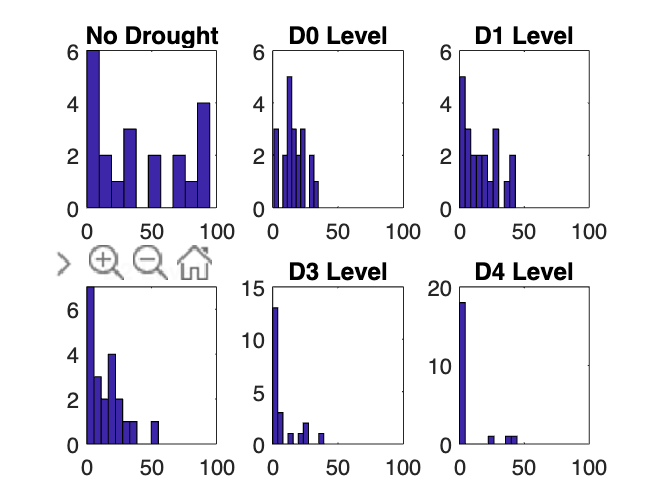


% %Histograms of drought severity
% figure 
% subplot(2, 3, 1)
% hist(dnone, 10);
% xlim([0 100])
% title("No Drought")
% 
% subplot(2, 3, 2)
% hist(d0, 10);
% xlim([0 100])
% title("D0 Level")
% 
% subplot(2, 3, 3)
% hist(d1, 10);
% xlim([0 100])
% title("D1 Level")
% 
% 
% subplot(2, 3, 4)
% hist(d2, 10);
% xlim([0 100])
% title("D2 Level")
% 
% subplot(2, 3, 5)
% hist(d3, 10);
% xlim([0 100])
% title("D3 Level")
% 
% 
% subplot(2, 3, 6)
% hist(d4, 10);
% xlim([0 100])
% title("D4 Level")

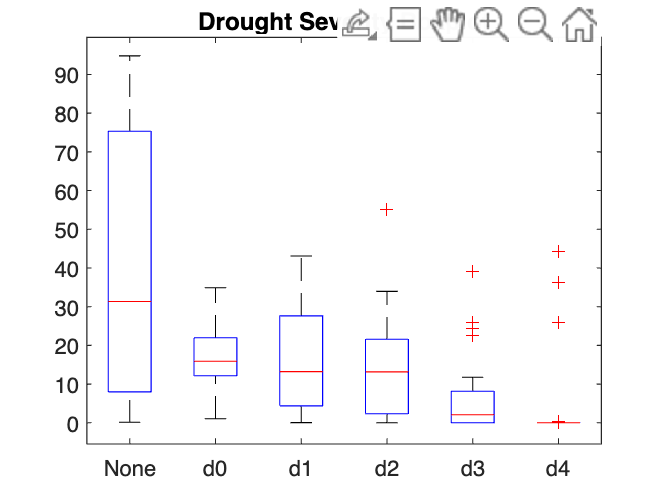

% %Box plots of drought severity
% droughtlevels= [dnone d0 d1 d2 d3 d4 ];
% lables = ["None", "d0", "d1", "d2", "d3", "d4"];
% figure
% boxplot(droughtlevels, lables);
% title("Drought Severity Boxplot");

droughtlevels= [years dnone d0 d1 d2 d3 d4 ];
drought_total_sum  = sum(droughtlevels(:, 3:7),2);


%Least Squares

%Drought vs Occurance
[p_occurance s]=polyfit(drought_total_sum , count_by_year, 1);
R_squared = 1 - (s.normr/norm(count_by_year - mean(count_by_year)))^2

R_squared = 0.0371

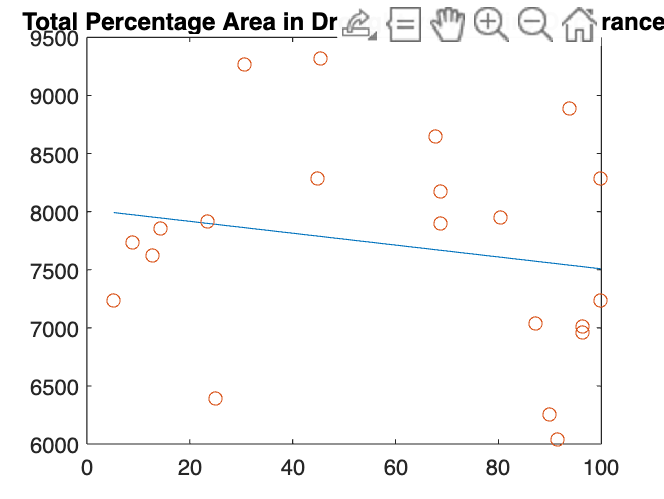


y_fit_occurance = polyval(p_occurance, drought_total_sum);


figure
plot(drought_total_sum, y_fit_occurance);
hold on;
plot(drought_total_sum, count_by_year, 'o')
title("Total Percentage Area in Drought vs Wildfire Occurance");
hold off;

xlim([0 100])
ylim([6000 9500])

R_squared = 0.0477

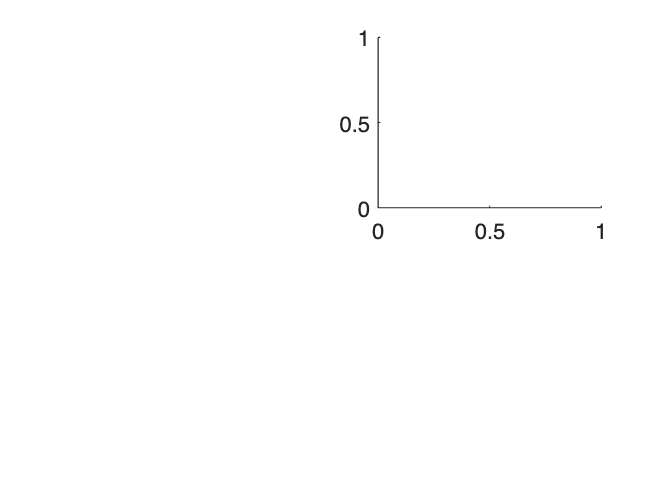



%Drought vs Acres
[p_acres, s]=polyfit(drought_total_sum, acres, 1);
y_fit_acres=polyval(p_acres, drought_total_sum);
R_squared = 1 - (s.normr/norm(acres - mean(acres)))^2

figure

plot(drought_total_sum, acres, 'o' );
hold on;
plot(drought_total_sum, y_fit_acres, '-b');
title("Total Percentage Area in Drought vs Acres Burned in Wildfire")
hold off;

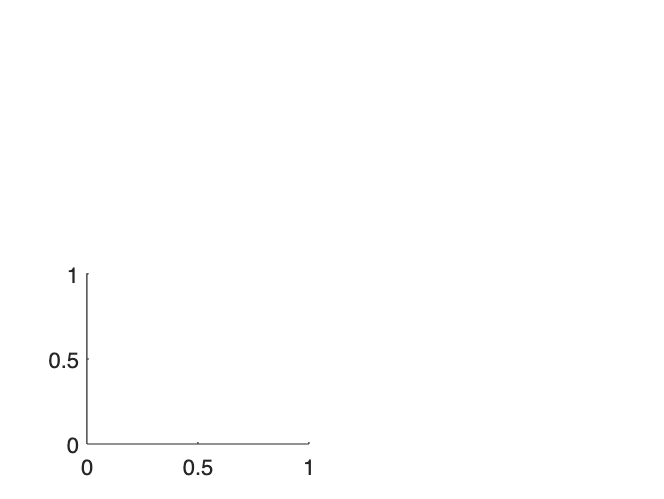



%Wind vs Occurance


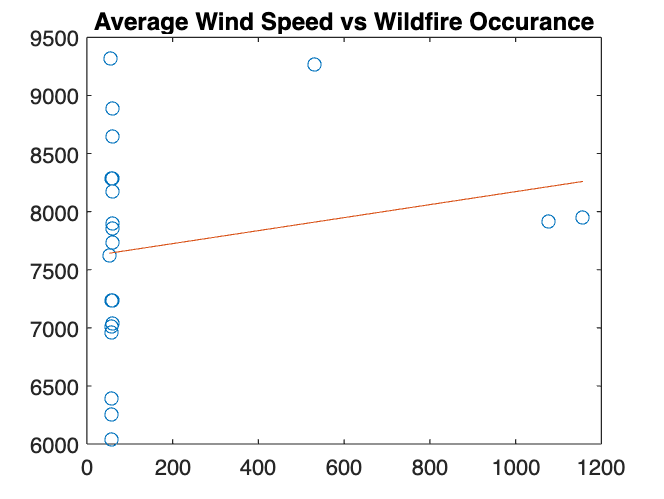

figure

plot(avg_wind, count_by_year, 'o');
p_wind_occ=polyfit(avg_wind, count_by_year, 1);
y_fit_wind_occ = polyval(p_wind_occ, avg_wind);
hold on;
plot(avg_wind, y_fit_wind_occ);
title("Average Wind Speed vs Wildfire Occurance")
hold off;

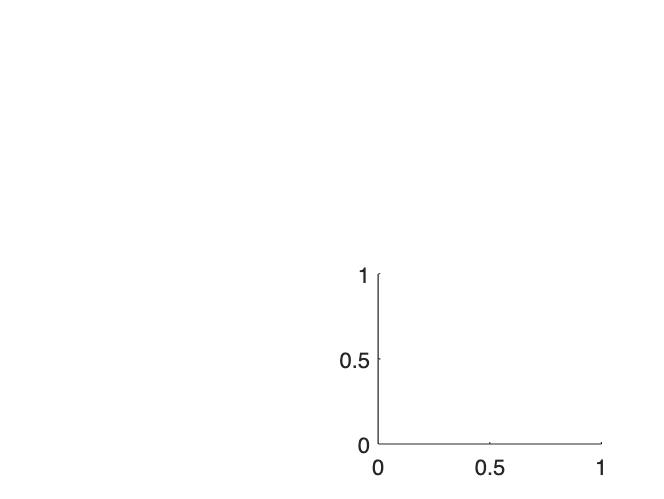



%Wind vs Acres


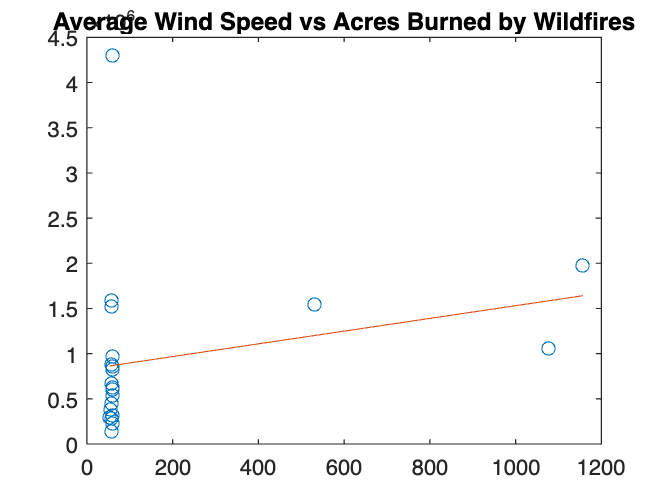

figure

plot(avg_wind, acres, 'o');
p_wind_acres=polyfit(avg_wind, acres, 1);
y_fit_wind_acres = polyval(p_wind_acres, avg_wind);
hold on;
plot(avg_wind, y_fit_wind_acres);
title("Average Wind Speed vs Acres Burned by Wildfires")
hold off;

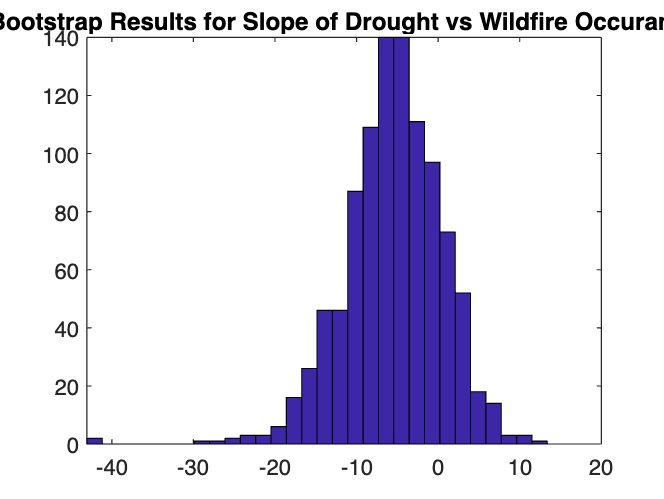

%Error Analysis: Bootstrap

%Drought vs occurance
p_bootstrp_occ = bootstrp(1000,'polyfit',drought_total_sum,count_by_year,1);

figure
hist(p_bootstrp_occ(:,1),30)
hold on; title("Bootstrap Results for Slope of Drought vs Wildfire Occurance"); hold off;

mean(p_bootstrp_occ(:,1)), std(p_bootstrp_occ(:,1))

ans = -5.4946

ans = 6.0125

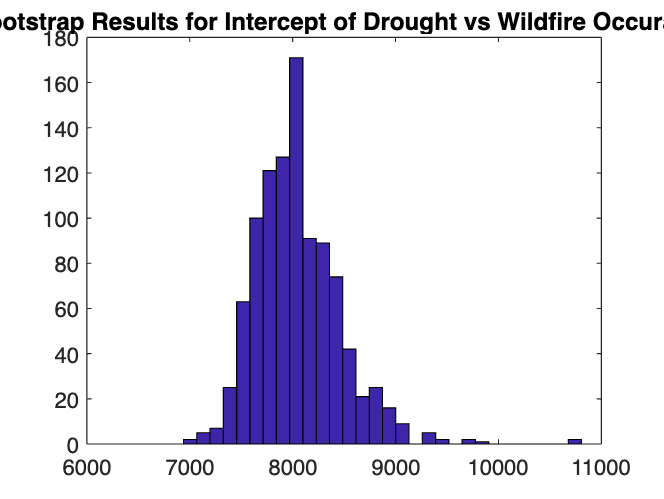


figure
hist(p_bootstrp_occ(:,2),30);
hold on; title("Bootstrap Results for Intercept of Drought vs Wildfire Occurance"); hold off;

mean(p_bootstrp_occ(:,2)), std(p_bootstrp_occ(:,2))

ans = 8.0500e+03

ans = 415.2950

%95 percent confidence interval for LS slope
LS_stats_sort_occ = sort(p_bootstrp_occ(:,1));
CI_OCC = prctile(LS_stats_sort_occ, [2.5,97.5])

CI_OCC =   -17.7652    5.2814




%Drought vs acres burned
p_bootstrp_acres = bootstrp(1000,'polyfit',drought_total_sum,acres,1);
figure
hist(p_bootstrp_acres(:,1),30)
mean(p_bootstrp_acres(:,1)), std(p_bootstrp_acres(:,1))

ans = 5.7312e+03

ans = 3.6747e+03

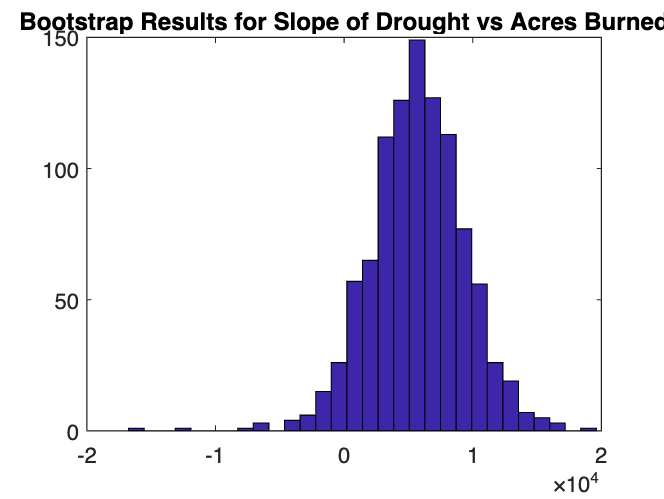

hold on; title("Bootstrap Results for Slope of Drought vs Acres Burned"); hold off;

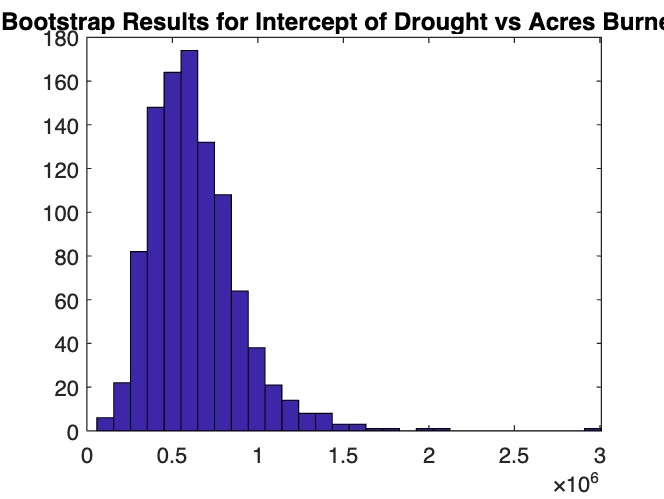



figure
hist(p_bootstrp_acres(:,2),30);
hold on; title("Bootstrap Results for Intercept of Drought vs Acres Burned"); hold off;

mean(p_bootstrp_acres(:,2)), std(p_bootstrp_acres(:,2))

ans = 6.3114e+05

ans = 2.6437e+05

%95 percent confidence interval for LS slope
LS_stats_sort_acres = sort(p_bootstrp_acres(:,1));
CI_ACRES = prctile(LS_stats_sort_acres, [2.5,97.5])

CI_ACRES = 1.0e+04 *

   -0.1279    1.2983



%Wind vs Occurance
p_bootstrap_windO = bootstrp(1000, 'polyfit', avg_wind, count_by_year, 1);
figure
hist(p_bootstrap_windO(:,1), 30);
mean(p_bootstrap_windO(:,1)), std(p_bootstrap_windO(:,2))

ans = 3.5337

ans = 1.5685e+03

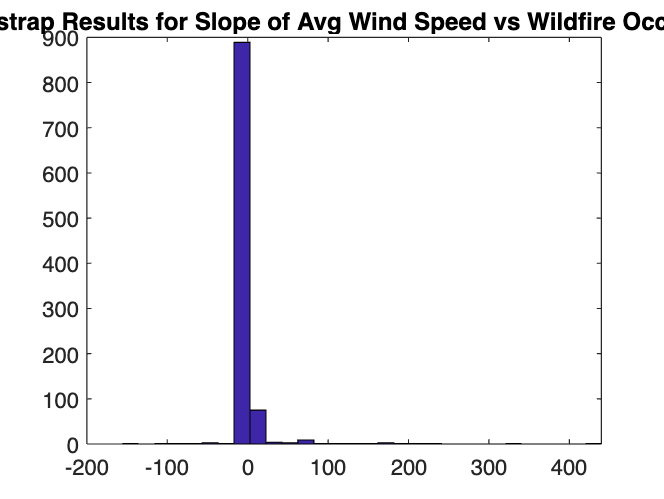

hold on; title("Bootstrap Results for Slope of Avg Wind Speed vs Wildfire Occurance"); hold off;

%95 Percent Confidence Interval
LS_stats_sort_WO = sort(p_bootstrap_windO(:,1));
CI_WIND_O = prctile(LS_stats_sort_WO, [2.5,97.5])

CI_WIND_O =    -0.0262   34.4524



%Wind vs Acres
p_bootstrap_windA = bootstrp(1000, 'polyfit', avg_wind, acres, 1);
figure
hist(p_bootstrap_windA(:,1), 30);
mean(p_bootstrap_windA(:,1)), std(p_bootstrap_windA(:,2))

ans = 2.3338e+03

ans = 8.7714e+05

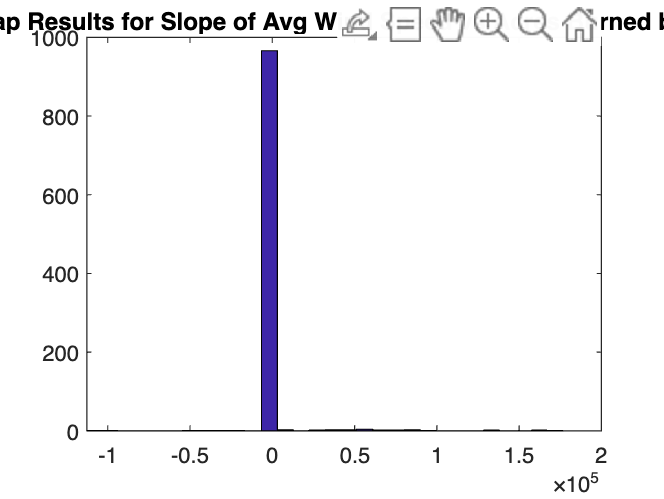

hold on; title("Bootstrap Results for Slope of Avg Wind Speed vs Acres Burned by Wildfire"); hold off;

%95 Percent Confidence Interval
LS_stats_sort_WA = sort(p_bootstrap_windA(:,1));
CI_WIND_A = prctile(LS_stats_sort_WA, [2.5,97.5])

CI_WIND_A = 1.0e+04 *

   -0.0076    1.7111


%Correlation Analysis

mat = [drought_total_sum, avg_wind, count_by_year, acres];

drought_occ =     1.0000   -0.1926
   -0.1926    1.0000


p1 =     1.0000    0.4029
    0.4029    1.0000


drought_acres =     1.0000    0.2183
    0.2183    1.0000


p2 =     1.0000    0.3417
    0.3417    1.0000


wind_occ =     1.0000    0.1993
    0.1993    1.0000


p3 =     1.0000    0.3863
    0.3863    1.0000


wind_acres =     1.0000    0.2505
    0.2505    1.0000


p4 =     1.0000    0.2735
    0.2735    1.0000


cor =     1.0000   -0.1196   -0.1926    0.2183
   -0.1196    1.0000    0.1993    0.2505
   -0.1926    0.1993    1.0000    0.1773
    0.2183    0.2505    0.1773    1.0000


p =     1.0000    0.6057    0.4029    0.3417
    0.6057    1.0000    0.3863    0.2735
    0.4029    0.3863    1.0000    0.4421
    0.3417    0.2735    0.4421    1.0000


[cor, p] = corrcoef(mat)

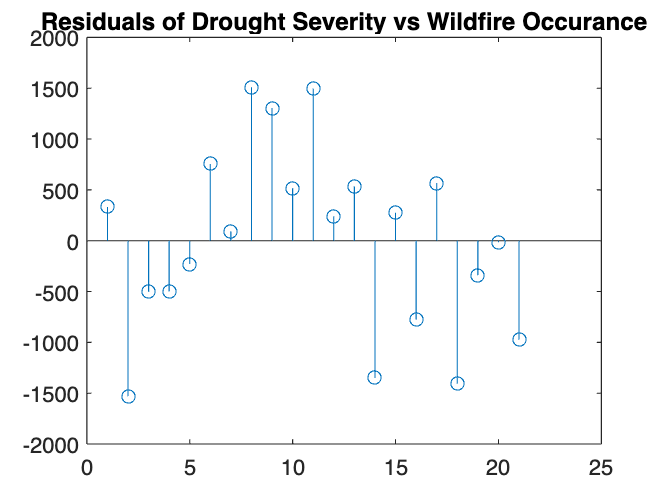

% Error Analysis: Test of residual normality (Chi square test)

%Drought vs Occurance
res_occ = y_fit_occurance - count_by_year;
figure
stem(res_occ);
title("Residuals of Drought Severity vs Wildfire Occurance")


numbins = 5;
[n_exp x] = hist(res_occ,numbins);%21 data points, 5 bins
n_syn = normpdf(x,mean(res_occ),std(res_occ)); %synthetic norm dist
%scale normal dist
ratio = n_syn ./ sum(n_syn);
n_syn = sum(n_exp)*ratio;
 
chi2 = sum((n_exp-n_syn).^2./n_syn)

chi2 = 1.4496


dof = length(n_exp) - 3;
chi2_crit =  chi2inv(0.95,dof)

chi2_crit = 5.9915

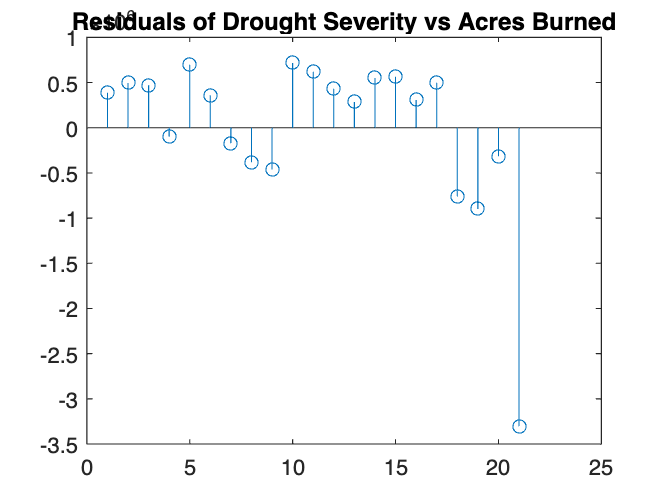


%Drought vs Acres Burned
res_acres = y_fit_acres - acres;
figure
stem(res_acres);
title("Residuals of Drought Severity vs Acres Burned")

numbins = 5;
[n_exp x] = hist(res_acres,numbins);%21 data points, 5 bins
n_syn = normpdf(x,mean(res_acres),std(res_acres)); %synthetic norm dist
%scale normal dist
ratio = n_syn ./ sum(n_syn);
n_syn = sum(n_exp)*ratio;
 
chi2 = sum((n_exp-n_syn).^2./n_syn)

chi2 = 22.1950


dof = length(n_exp) - 3;
chi2_crit =  chi2inv(0.95,dof)

chi2_crit = 5.9915

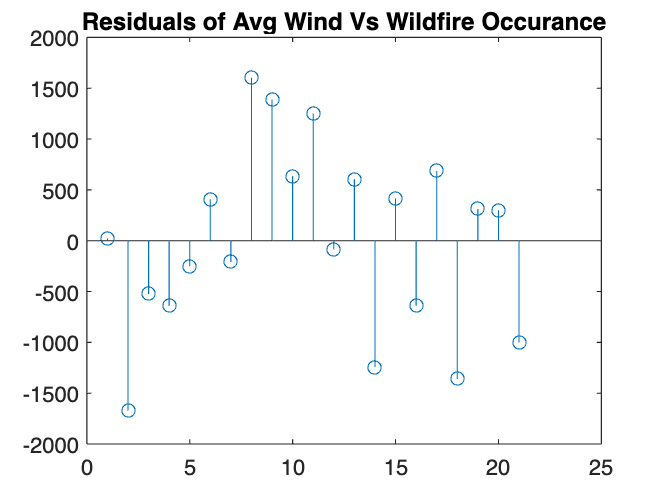


%Wind vs Occurance
res_windO = y_fit_wind_occ- count_by_year;
figure
stem(res_windO)
title("Residuals of Avg Wind Vs Wildfire Occurance");

%Chi Squared Test
[n_exp x] = hist(res_windO,numbins);%21 data points, 5 bins
n_syn = normpdf(x,mean(res_windO),std(res_windO)); %synthetic norm dist
%scale normal dist
ratio = n_syn ./ sum(n_syn);
n_syn = sum(n_exp)*ratio;
 
chi2 = sum((n_exp-n_syn).^2./n_syn)

chi2 = 2.2984


dof = length(n_exp) - 3;
chi2_crit =  chi2inv(0.95,dof)

chi2_crit = 5.9915

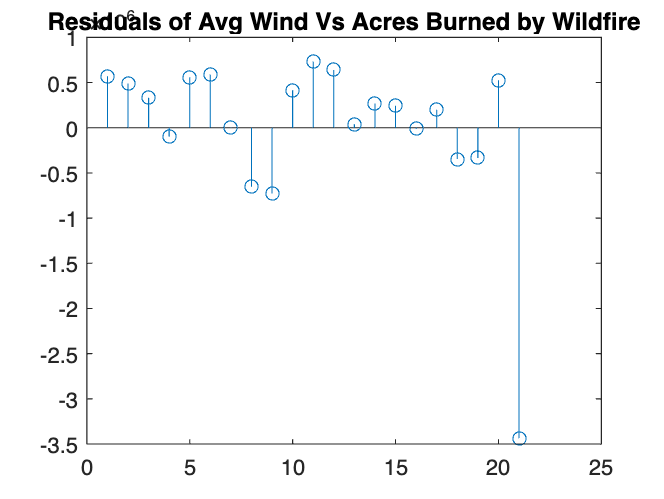


%Wind Vs Acres
res_windA = y_fit_wind_acres- acres;
figure
stem(res_windA)
title("Residuals of Avg Wind Vs Acres Burned by Wildfire");

%Chi Squared Test
[n_exp x] = hist(res_windA,numbins);%21 data points, 5 bins
n_syn = normpdf(x,mean(res_windA),std(res_windA)); %synthetic norm dist
%scale normal dist
ratio = n_syn ./ sum(n_syn);
n_syn = sum(n_exp)*ratio;
 
chi2 = sum((n_exp-n_syn).^2./n_syn)

chi2 = 40.5864


dof = length(n_exp) - 3;
chi2_crit =  chi2inv(0.95,dof)

chi2_crit = 5.9915

%Time Series by Drought Severity
dtd0total=detrend(d0total);
[Pxx,f] =periodogram(dtd0total, [], length(dtd0total), 1);
nn=2:length(f);
figure
subplot(1,2,1);
semilogx(1./f(nn), Pxx(nn))
xlabel("Weeks");
ylabel("PSD");
subplot(1,2,2);
plot(d0total, "color", "#e8c70e");
xticks(1:104:1096);
xticklabels(years(1:2:end));
ylabel("% Area in D0 Drought")

dtd1total=detrend(d1total);
[Pxx,f] =periodogram(dtd1total, [], length(dtd1total), 1);
nn=2:length(f);
figure
subplot(1,2,1);
semilogx(1./f(nn), Pxx(nn))
xlabel("Weeks")
ylabel("PSD");
subplot(1,2,2);
plot(d1total, "color", "#ff9005");
xticks(1:104:1096);
xticklabels(years(1:2:end));
ylabel("% Area in D1 Drought")


dtd2total=detrend(d2total);
[Pxx,f] =periodogram(dtd2total, [], length(dtd2total), 1);
nn=2:length(f);
figure
subplot(1,2, 1)
semilogx(1./f(nn), Pxx(nn))
xlabel("Weeks")
ylabel("PSD");
subplot(1,2,2)
plot(d2total, "color", "#ff7a05");
xticks(1:104:1096);
xticklabels(years(1:2:end));
ylabel("% Area in D2 Drought")


dtd3total=detrend(d3total);
[Pxx,f] =periodogram(dtd3total, [], length(dtd3total), 1);
nn=2:length(f);
figure
subplot(1,2, 1)
semilogx(1./f(nn), Pxx(nn))
ylabel("PSD");
xlabel("Weeks")
subplot(1,2,2)
plot(d3total, "color", "#f9530b");
xticks(1:104:1096);
xticklabels(years(1:2:end));
ylabel("% Area in D3 Drought")


dtd4total=detrend(d4total);
[Pxx,f] =periodogram(dtd4total, [], length(dtd4total), 1);
nn=2:length(f);
figure
subplot(1,2, 1)
semilogx(1./f(nn), Pxx(nn))
ylabel("PSD");
xlabel("Weeks")
subplot(1,2,2)
plot(d4total, "color", "#ff0000");
xticks(1:104:1096);
xticklabels(years(1:2:end));
ylabel("% Area in D4 Drought")